**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

**Q8 Post denoising, develop and apply an appropriate methodology for correcting for the discontinuities that arise within the data records and  discuss when such corrections are appropriate and when they are not.**

**Would your developed approach continue to work for real-time (streamed) data? Discuss why or why not and the issues and complexities that real-time (streamed) data introduces. **

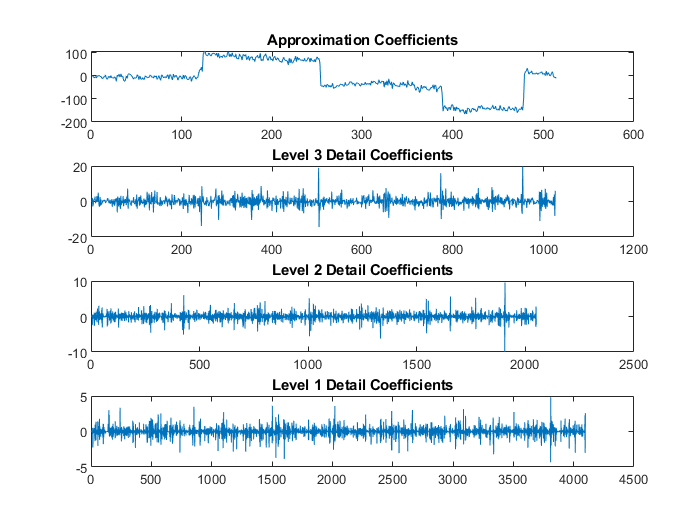

clear memory;
clearvars;
clc;

load('-mat', 'processed_data_details');

% level 4 wavelet decomposition
[c,l] = wavedec(denoised_data(1).x,4,'db2');
approximationCoeff = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

figure();
subplot(4,1,1)
plot(approximationCoeff)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

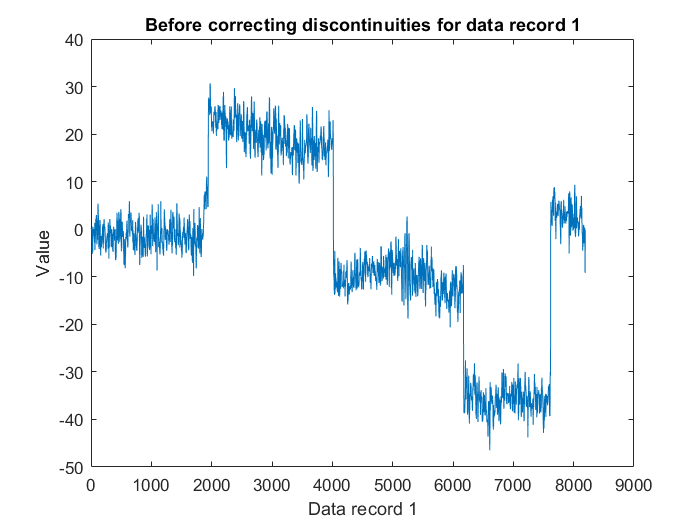


c(length(approximationCoeff) + 1 : length(c)) = 0;
figure();
plot(denoised_data(1).x)
title('Before correcting discontinuities for data record 1');
xlabel('Data record 1');
ylabel('Value');

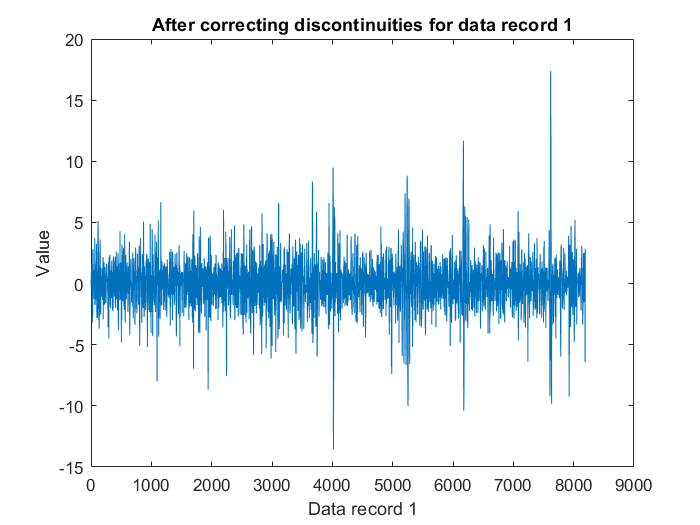


figure();

corrected_data = denoised_data(1).x - waverec(c, l, 'db2');
figure();
plot(corrected_data)
title('After correcting discontinuities for data record 1');
xlabel('Data record 1');
ylabel('Value');


for i = 1:length(sanitized_data)
    
    level = 7;
    [c, l] = wavedec(sanitized_data(i).x, level, 'db2');
    approx = appcoef(c, l, 'db2');
    c(length(approximationCoeff) + 1 : length(c)) = 0;
    a = denoised_data(1).x - waverec(c, l, 'db2');
    sanitized_data(i).x = a;
    
end

**Ans:**

Various methodologies that work for correcting the discontinuities are median filtering,wavelet recontruction and so on. Median filtering works for realtime but wavelet denoising does not so we need to find a new way around it.

Our selected approach of removing wavelet reconstructed data from the main source will work with real time data because the wavelet denoising alone doesnt work for realtime data. So we need to find a way to reconstruct the wavelet and remove it from the denoised dataset. Wavelet denoising doesn't work with real time data because in wavelet denoising  we are converting signal to wavelet domain and getting the coefficient. In our approach, we are first find the wavelet decomposition and using that to find approximation coefficient which is then used for wavelet recontruction.

The issues and complexities introduced by real  time data are, first of all we have to make sure that data is sent generically to mitigate the downstream impact of changes. Real time data being immutable cause issues in certain types of transformations. One of the issues is its rigid processing pipelines. Since the real time streamed data is designed to promote loose coupling, we need to employ a pipeline extraction framework to mitigate the issues of tightly bound stacks. Real time data brings in issues of scalability bottlenecks. One of the complexities of real time streamed data is the quality maintainence  as the lack of quality is propagated though the analytics network.

**Ex8 Q9 Apply matching filtering to locate when the time domain event described by the variable event exists within each of the given data records.**

**Discuss the assumptions underlying matched filtering and which situations it will work in and which it will not.**

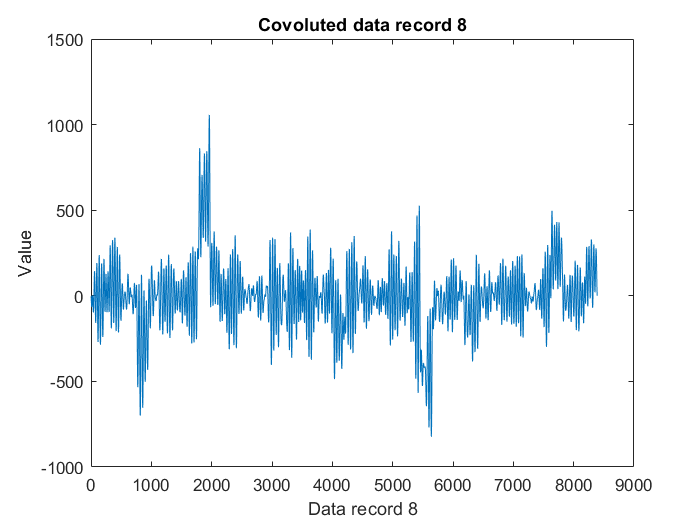

convoluded_data = conv(sanitized_data(8).x, event);
figure();
plot(convoluded_data);
title('Covoluted data record 8');
xlabel('Data record 8');
ylabel('Value');


%Plotting convoluted data for all data points in sets of 25
display('Convolued Data records 1 to 25'); 

Convolued Data records 1 to 25


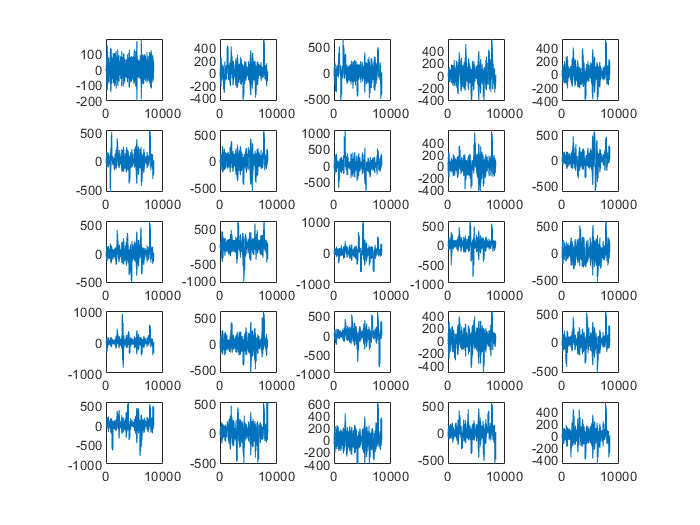

figure();
for i = 1:25
    
    subplot(5, 5, i);
    convoluded_data = conv(sanitized_data(i).x, event);
    plot(convoluded_data);
        
end

hold off;


display('Convoluted Data records 26 to 50'); 

Convoluted Data records 26 to 50


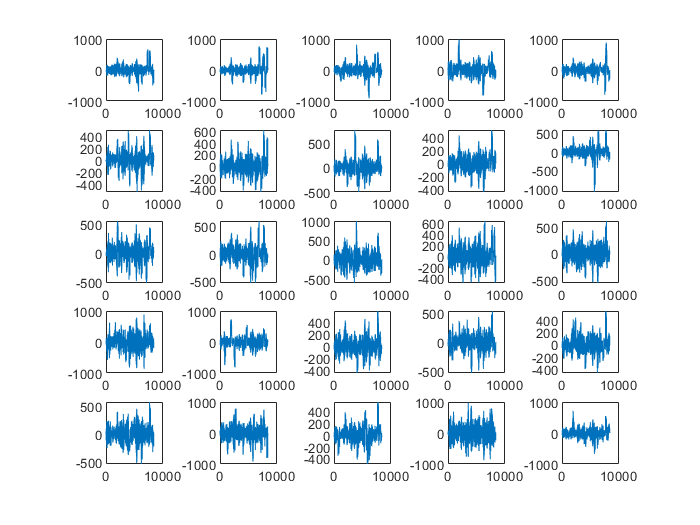

figure();
j = 1;
for i = 26:50
   
    subplot(5, 5, j);
    convoluded_data = conv(sanitized_data(i).x, event);
    plot(convoluded_data);
    j = j + 1;
    
end
hold off;


display('Convoluted Data records 51 to 75'); 

Convoluted Data records 51 to 75


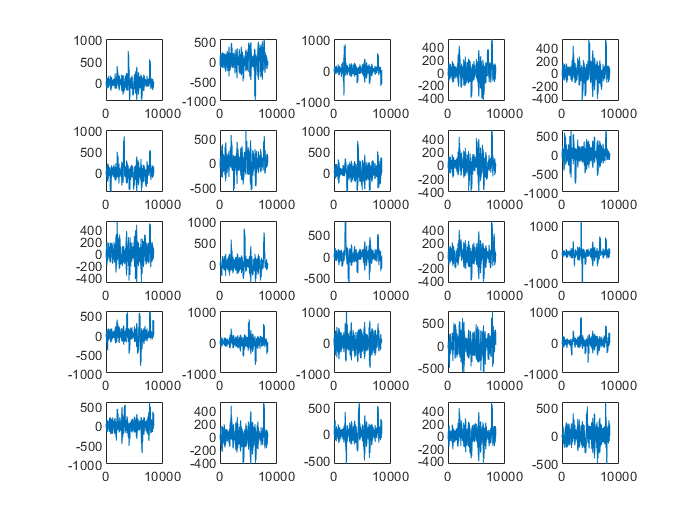

figure();
j = 1;
for i = 51:75

    subplot(5, 5, j);
    convoluded_data = conv(sanitized_data(i).x, event);
    plot(convoluded_data);
    j = j + 1;
    
end




display('Convoluted Data record 76 to last record'); 

Convoluted Data record 76 to last record


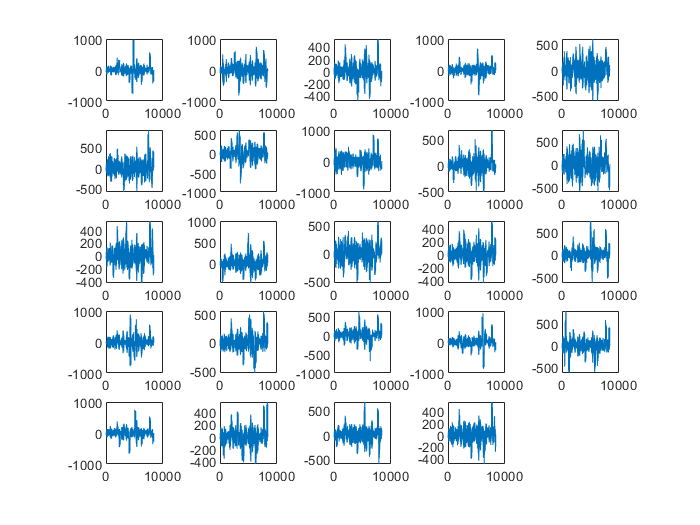

figure();
j = 1;
for i = 76:length(sanitized_data)

    subplot(5, 5, j);
    convoluded_data = conv(sanitized_data(i).x, event);
    plot(convoluded_data);
    j = j + 1;
    
end

**Q9 Discussion**

The assumption underlying matched filtering is that it comprises only of target returns and no noise components. Noise signal is assumed to be an additive random process that is uncorrelated with target. Therefore we need to get the data convoluted to apply matched filtering. Matched filtering will not work in this case as the signal gets spread across the time domain. Matched filter works in situations where a known signal is sent out, and the reflected signal is examined for common elements of the out-going signal. Matched filtering is a demodulation technique which is convolving unknown signal with conjugated time reversed version of the template.